# Week 4 Discussion Examples

## 1. Dynamic System Definition

% polynomial p = s^3 + 3s^2 - 2s + 4;
p = [1 3 -2 4];

% find roots:
r = roots(p)

r =   -3.8026 + 0.0000i
   0.4013 + 0.9439i
   0.4013 - 0.9439i



% find polynomial with roots:
p = poly(r)

p =     1.0000    3.0000   -2.0000    4.0000



% define another polynomial q = s^3 - 2s^2 + 3s + 4;
q = [1 -2 3 4];

% polynomial multiplication: p*q
conv(p,q)

ans =     1.0000    1.0000   -5.0000   21.0000   -2.0000    4.0000   16.0000


## 2. Analyzing Transfer Functions:

% define transfer function: F(s) = N(s)/D(s)
num = [1 3];
den = [3 2 0];
g = tf(num,den)

g =
 
     s + 3
  -----------
  3 s^2 + 2 s
 
Continuous-time transfer function.




% find zeros
zero(g)

ans = -3


% find poles
pole(g)

ans =          0
   -0.6667


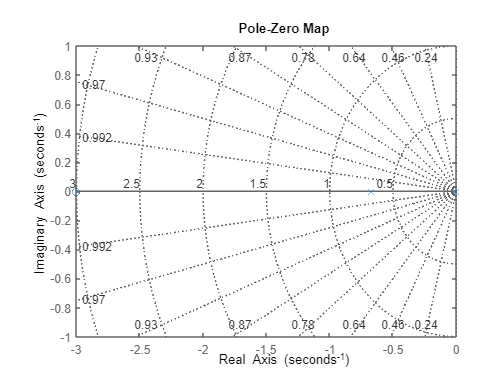

% plot pole-zero map
pzmap(g); grid on


% define system poles, zeros, and gain
z = [-1 2];
p = [-1 -1+3i -1-3i];
k = 5;

h = zpk(z,p,k)

h =
 
      5 (s+1) (s-2)
  ---------------------
  (s+1) (s^2 + 2s + 10)
 
Continuous-time zero/pole/gain model.




h1 = tf(h)

h1 =
 
     5 s^2 - 5 s - 10
  -----------------------
  s^3 + 3 s^2 + 12 s + 10
 
Continuous-time transfer function.




% find transfer function
% 20s+20/( s^5 + 3s^4 + 2s^3 -1 )

% s = tf('s');
s = sym('s');
a = sym('a');
G2 = (a*s+20) /( s^5 + 3*s^4 + 2*s^3 -1 )

$$G2 = \frac{a\,s+20}{s^{5}+3\,s^{4}+2\,s^{3}-1}$$


% alternative way of defining transfer function
s = tf('s');
g = 20*(s+1) / (s^5 + 3*s^4 + 2*s^3 + s - 1)

g =
 
           20 s + 20
  ---------------------------
  s^5 + 3 s^4 + 2 s^3 + s - 1
 
Continuous-time transfer function.



## 3. Block Manipulations

% series connection
series(g,h)

ans =
 
                                 100 (s+1)^2 (s-2)
  --------------------------------------------------------------------------------
  (s+1) (s-0.5071) (s^2 + 3.556s + 3.368) (s^2 - 0.0492s + 0.5854) (s^2 + 2s + 10)
 
Continuous-time zero/pole/gain model.



% parallel connection
parallel(g,h)

ans =
 
     5 (s+1.171) (s+1) (s+2.494) (s^2 - 4.002s + 5.647) (s^2 + 1.337s + 2.548)
  --------------------------------------------------------------------------------
  (s+1) (s-0.5071) (s^2 + 3.556s + 3.368) (s^2 - 0.0492s + 0.5854) (s^2 + 2s + 10)
 
Continuous-time zero/pole/gain model.



% unity negative feedback
feedback(h, [1], -1)

ans =
 
  5 (s-2) (s+1)
  -------------
  s (s+1) (s+7)
 
Continuous-time zero/pole/gain model.



% non-unity positve feedback
feedback(h, g, +1)

ans =
 
       5 (s-0.5071) (s+1) (s-2) (s^2 + 3.556s + 3.368) (s^2 - 0.0492s + 0.5854)
  -----------------------------------------------------------------------------------
  (s+1) (s+0.939) (s^2 - 2.257s + 1.955) (s^2 + 5.138s + 9.311) (s^2 + 1.18s + 11.12)
 
Continuous-time zero/pole/gain model.



## 4. System Response

% define a first order system:
gf = tf([1], [0.1 1])

gf =
 
      1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



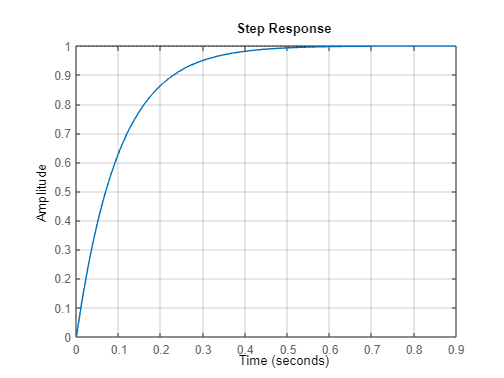


% step response of this system:
figure;
step(gf)
grid on;

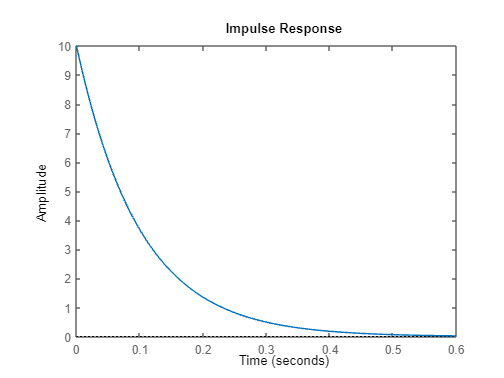


% impulse responsne of this system:
figure;
impulse(gf)

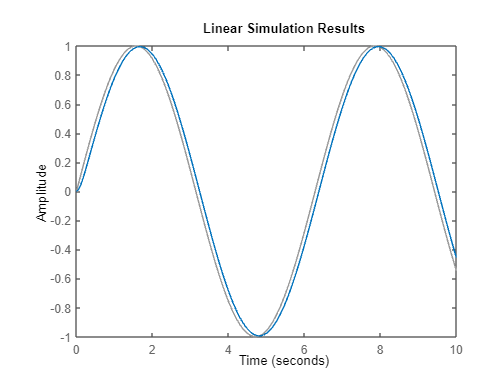


% response of this system to a sinusoidal input:
% clc; clf;
t = [0: 0.025: 10];
u = sin(t); 
lsim(gf, u, t)

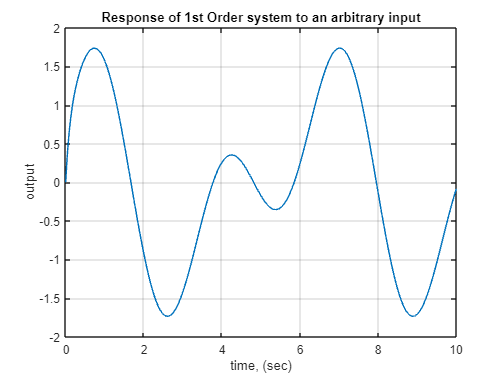


% response of this system to an arbitrary input:
u = cos(t) + sin(2*t);
y = lsim(gf, u, t);

plot(t,y);
grid on;
title("Response of 1st Order system to an arbitrary input");
xlabel('time, (sec)');
ylabel('output');

## Solving Block Manipulation Example with MATLAB:

% define blocks with tf() - knowing N(s) and D(s), and zpk() - knowing
% poles, zeros and gains

g1 = zpk([1],[-1 -3],1)

g1 =
 
     (s-1)
  -----------
  (s+1) (s+3)
 
Continuous-time zero/pole/gain model.



g2 = tf([5 5],[1 3 7])

g2 =
 
     5 s + 5
  -------------
  s^2 + 3 s + 7
 
Continuous-time transfer function.



g3 = tf([1 2 10],conv([1 1],[2 0.1 3]))

g3 =
 
        s^2 + 2 s + 10
  ---------------------------
  2 s^3 + 2.1 s^2 + 3.1 s + 3
 
Continuous-time transfer function.



g4 = tf([1 -3],conv([1 -1],[1 0 3]))

g4 =
 
         s - 3
  -------------------
  s^3 - s^2 + 3 s - 3
 
Continuous-time transfer function.



g5 = tf([6 0 -6],conv([1 1],[1 -3 0]))

g5 =
 
      6 s^2 - 6
  -----------------
  s^3 - 2 s^2 - 3 s
 
Continuous-time transfer function.



g6 = zpk([-7], [-1 -3], [1])

g6 =
 
     (s+7)
  -----------
  (s+1) (s+3)
 
Continuous-time zero/pole/gain model.



% g3 & g6 are in series -> g36
g36=series(g3,g6);
% g3 & g4 are in parallel -> g34
g34=parallel(g3,g4);
% g2 & g36 are in negative feedback -> g236
g236=feedback(g2,g36);
% g236 & g34 are in series -> g2346
g2346=series(g236,g34);
% g1 & g2346 are in series -> g12346
g12346=series(g1,g2346);
% g5 & g12346 are in series -> G
G=series(g12346,g5)

G =
 
              15 (s+1)^4 (s-1.373) (s-1)^2 (s+3) (s^2 + 0.05s + 1.5) (s^2 - 0.2681s + 2.371) (s^2 + 4.641s + 11.98)
  ------------------------------------------------------------------------------------------------------------------------------
  s (s-3) (s+3) (s+1)^4 (s-1) (s^2 + 5.692s + 9.036) (s^2 + 0.05s + 1.5) (s^2 - 1.294s + 3.069) (s^2 + 3) (s^2 + 2.652s + 7.447)
 
Continuous-time zero/pole/gain model.



% G is in negative unity feedback -> 
% Gcl - close loop transfer function
gcl = tf(feedback(G,[1]))

gcl =
 
                                                                                                                                               
  15 s^14 + 120.8 s^13 + 435 s^12 + 699.8 s^11 + 157.7 s^10 - 642.6 s^9 - 2635 s^8 - 4686 s^7 - 1227 s^6 + 2860 s^5 + 4829 s^4 + 6683 s^3      
                                                                                                                                               
                                                                                                                     + 1057 s^2 - 5036 s - 2633
                                                                                                                                               
  ---------------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                

% simplify - find minimal polynomials for Gcl
gclMin = minreal(gcl)

gclMin =
 
                                                                                                                                  
                 15 s^10 + 90 s^9 + 271.5 s^8 + 226.5 s^7 - 115.5 s^6 - 457.5 s^5 - 1283 s^4 - 1348 s^3 + 526.5 s^2 + 1490 s + 585
                                                                                                                                  
  ------------------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                                  
  s^14 + 8.05 s^13 + 27.9 s^12 + 42.8 s^11 - 33.65 s^10 - 380.2 s^9 - 1244 s^8 - 3575 s^7 - 7439 s^6 - 1.154e04 s^5 - 1.556e04 s^4 - 1.519e04 s^3 
                                                                                                                                                  
        

zpk(gclMin)

ans =
 
                         15 (s-1.373) (s-1) (s+1)^4 (s^2 - 0.2681s + 2.371) (s^2 + 4.641s + 11.98)
  ------------------------------------------------------------------------------------------------------------------------
  (s-2.928) (s+1)^4 (s-0.2112) (s^2 + 6.053s + 10.58) (s^2 - 0.1857s + 2.78) (s^2 - 1.569s + 3.856) (s^2 + 2.891s + 8.345)
 
Continuous-time zero/pole/gain model.

